## Matlab Startup File

This m-File code prepare the enviroment to provide access to auxilliary files and sub-folders.

clear; clc; close all;
% format short eng                              
[ProjectFolder,AuxFcn_GS] = AuxFcn_Matlab_Startup_File_001; % Project Startup Folder & Graphical Settings

load('E2038.mat');   % Suppose data is in a variable pz
% % % % % % % % % % % % % % % % % % % % % % % 
%  Test Mean-subtraction to remove DC offset/baseline
dataTest1 = p(:,1) - mean(p(1:100,1));
dataTest2 = p(:,2) - mean(p(1:100,2));
dataTest3 = p(:,3) - mean(p(1:100,3));
dataTest4 = p(:,4) - mean(p(1:100,4));
dataTest5 = p(:,5) - mean(p(1:100,5));
dataTest6 = p(:,6) - mean(p(1:100,6));
dataTest7 = p(:,7) - mean(p(1:100,7));
dataTest8 = p(:,8) - mean(p(1:100,8));
dataTest9 = p(:,9) - mean(p(1:100,9));
dataTest10 = p(:,10) - mean(p(1:100,10));
dataTest11= p(:,11) - mean(p(1:100,11));
dataTest12 = p(:,12) - mean(p(1:100,12));

% % % % % % % % % % % % % % % % % % % % 
data = dataTest3 * 100; % pressure [mbar]   % Adjust column to your data of interest
Fs = fs;             % Sampling frequency in Hz
t = (0:length(data)-1)'/Fs;

## Decompose signal using the EWT


% Perform the decomposition using ewt
% [mra,cfs,wfb,info] = ewt(data, ...
%     MaxNumPeaks=5, ...
%     SegmentMethod='geomean', ...
%     FrequencyResolution=7.803e-06, ...
%     LogSpectrum=false);
MaxNumPeaks = 5;
 [mra, cfs, wfb, info] = ewt(data, 'MaxNumPeaks',MaxNumPeaks);
 % [mra,cfs,wfb,info] = ewt(data, ...
 %    PeakThresholdPercent=13.5, ...
 %    SegmentMethod='geomean', ...
 %    FrequencyResolution=7.803e-06, ...
 %    LogSpectrum=false);


## Signal Reconstruction 

PeakFrequencies = Fs * info.PeakFrequencies

PeakFrequencies =    588.7752e+000
   313.5406e+000
   249.6975e+000
    86.5429e+000
     4.2562e+000


freqPassbands = Fs * info.FilterBank.Passbands

freqPassbands =    429.8769e+000   500.0000e+003
   280.9096e+000   429.8769e+000
   147.5485e+000   280.9096e+000
    21.2810e+000   147.5485e+000
     0.0000e+000    21.2810e+000


%% Signal Reconstruction  
% Logical array for selecting reconstruction elements
% levelForReconstruction = [false,true,true,true,true,true,true,true,true,true,true,true,true,true,true,true,true,true,true,true];
% levelForReconstruction = [false,true,true,true,true,true,true,true,true,true];
levelForReconstruction = logical([zeros(1,1) ones(1,4)]);
% Sum down the rows of the selected multiresolution signals
SignalRecon = sum(mra(:,levelForReconstruction),2);

## Signal Reconstruction Verification

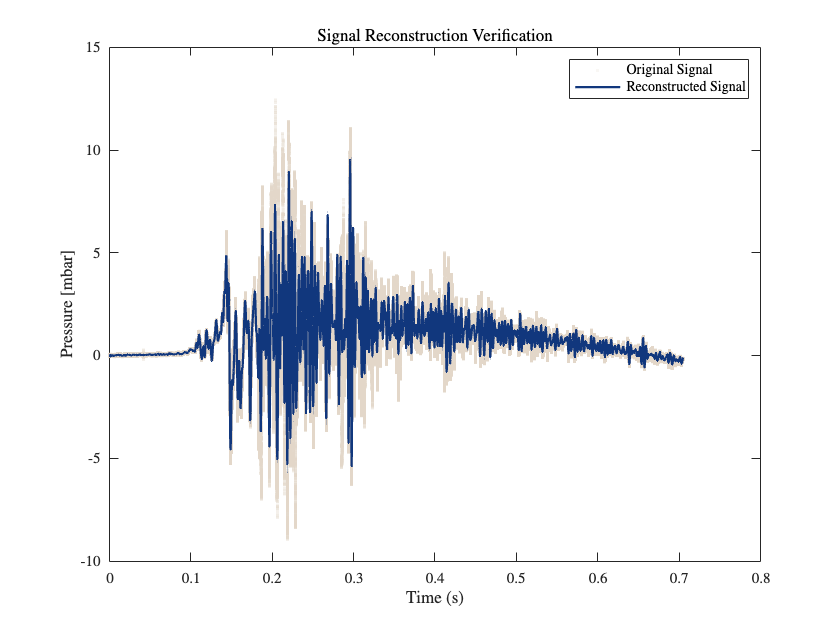

figure;
scatter(t, data, '.', ...
    'MarkerEdgeColor', AuxFcn_GS.LUCopper_Light, ...
    'MarkerEdgeAlpha', 0.2);   % <--- Transparency set here (20% opaque)
hold on
plot(t, SignalRecon, 'Color',AuxFcn_GS.LUBlue,LineWidth=1.5); 
title('Signal Reconstruction Verification');
% grid on;
xlabel('Time (s)'); ylabel('Pressure [mbar]');
legend('Original Signal','Reconstructed Signal')
box on

### **Verification: Compute sum of the MRA components results in perfect reconstruction of the signal.**

SignalReconPerferctCheck = max(abs(data-sum(mra,2)))

SignalReconPerferctCheck =    697.0534e-006


SignalReconFilteredCheck = max(abs(data - SignalRecon))

SignalReconFilteredCheck =      7.1675e+000


### **Verification: Compute energy preservation of the EWT analysis coefficients.**

Energy_original = norm(data,2)^2; % Sum of squared amplitudes is the same as sum(abs(data).^2)!!!!
cfsenergy = sum(sum(abs(cfs).^2));
EnergyPreservCheck = [Energy_original cfsenergy]

EnergyPreservCheck =      2.4671e+006     2.4671e+006


### **Verification: Compute Energy Ratio**

energy_ratio = cfsenergy / Energy_original;
disp(['EWT Reconstruction Energy Preservation Ratio: ', num2str(energy_ratio)]);

EWT Reconstruction Energy Preservation Ratio: 0.99999


### **Verification: Compute Energy Relative Difference**

% energy_relative_diff = abs(Energy_original - cfsenergy) / Energy_original;
% Energy_SignalRecon = norm(SignalRecon,2)^2;% Sum of squared amplitudes
Energy_SignalRecon = sum(abs(data).^2); % Sum of squared amplitudes
PartialSignalRecon_Energy_Retention = (Energy_SignalRecon / Energy_original) * 100; % Percentage of energy retained
disp(['EWT Partial Reconstruction Energy Preservation Ratio: ', num2str(PartialSignalRecon_Energy_Retention), '[%]']);

EWT Partial Reconstruction Energy Preservation Ratio: 100[%]


### **Verification: Compute Impulse Ratio**

Impulse_original = trapz(t, data);
SignalRecon_Impulse = trapz(t, SignalRecon);
impulse_preserv_check = [Impulse_original SignalRecon_Impulse]

impulse_preserv_check =    596.0042e-003   596.0042e-003


impulse_ratio = SignalRecon_Impulse/Impulse_original

impulse_ratio =      1.0000e+000


### **Verification: Compute Impulse Relative Difference**

impulse_relative_diff = ((SignalRecon_Impulse - Impulse_original)/Impulse_original) * 100

impulse_relative_diff =      1.3197e-006


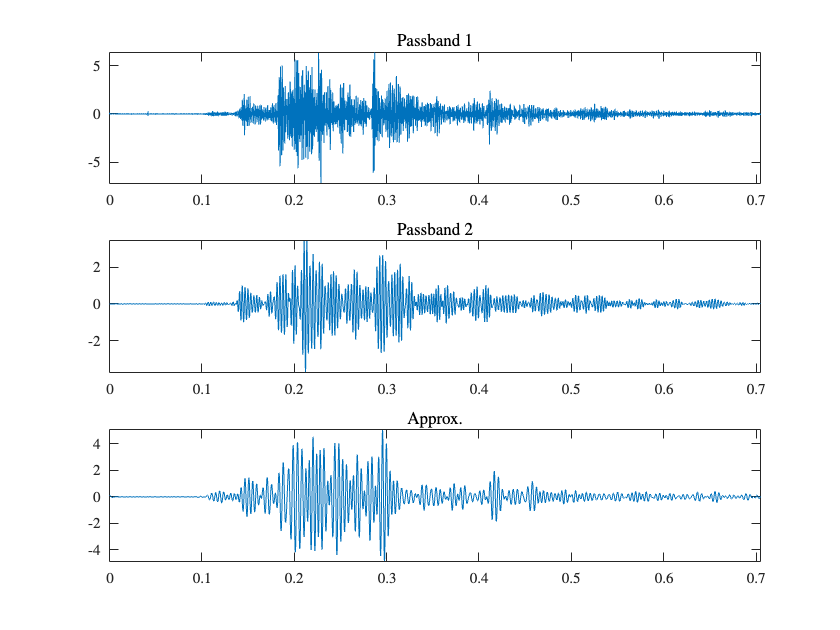


numplots = size(mra,2);
numplots = 3;

figure
for k=1:numplots
    subplot(numplots,1,k)
    plot(t,mra(:,k))
    if k~=numplots
        title(["Passband "+num2str(k)])
    else
        title("Approx.")
    end
    axis tight
end

### Visualizing Energy Distribution

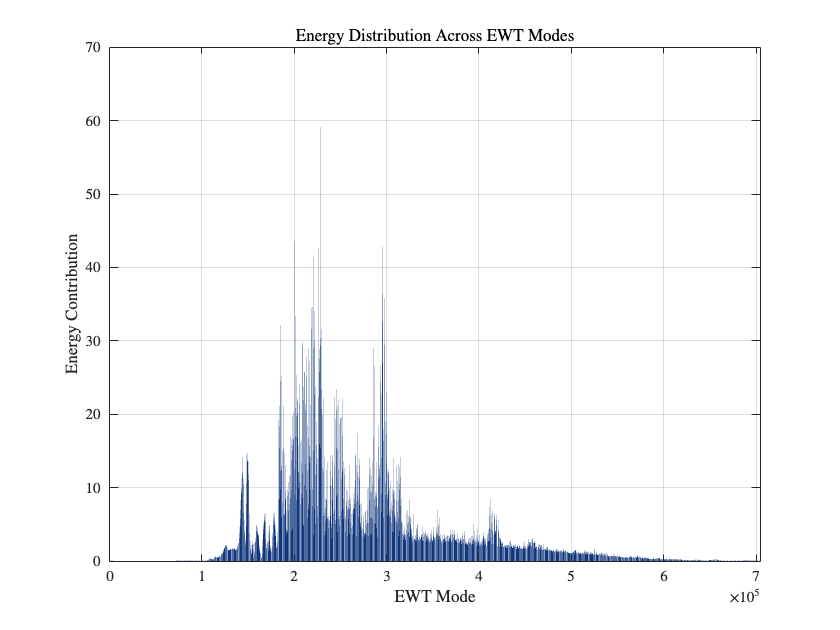

energy_per_band = sum(abs(cfs).^2, 2); % Energy per EWT mode
figure;
bar(energy_per_band,'FaceColor',AuxFcn_GS.LUBlue);
xlabel('EWT Mode');
ylabel('Energy Contribution');
title('Energy Distribution Across EWT Modes');
grid on;

% MaxNumPeaks = 5;
%         [mra_ewt, cfs2, wfb2, info2] = ewt(data, 'MaxNumPeaks',MaxNumPeaks);
% numplots2 = size(mra,2);
% figure
% for k=1:numplots2
%     subplot(numplots2,1,k)
%     plot(t,mra_ewt(:,k))
%     if k~=numplots2
%         title(["Passband "+num2str(k)])
%     else
%         title("Approx.")
%     end
%     axis tight
% end
%         PeakFrequencies2 = Fs * info2.PeakFrequencies
%         freqPassbands2 = Fs * info2.FilterBank.Passbands